# Operaciones matriciales

Las operaciones matriciales dentro de MATLAB siguen las **reglas del álgebra lineal** que se estudian en el instituto o en la universidad.

Para obtener más información, o un breve repaso, puede consultar el material adjunto en material adicional.

## Operaciones matriciales

En la siguiente tabla se muestran las operaciones matriciales de las que se dispone dentro de MATLAB.

**Figura 1.** Todas las operaciones matriciales dentro de MATLAB.

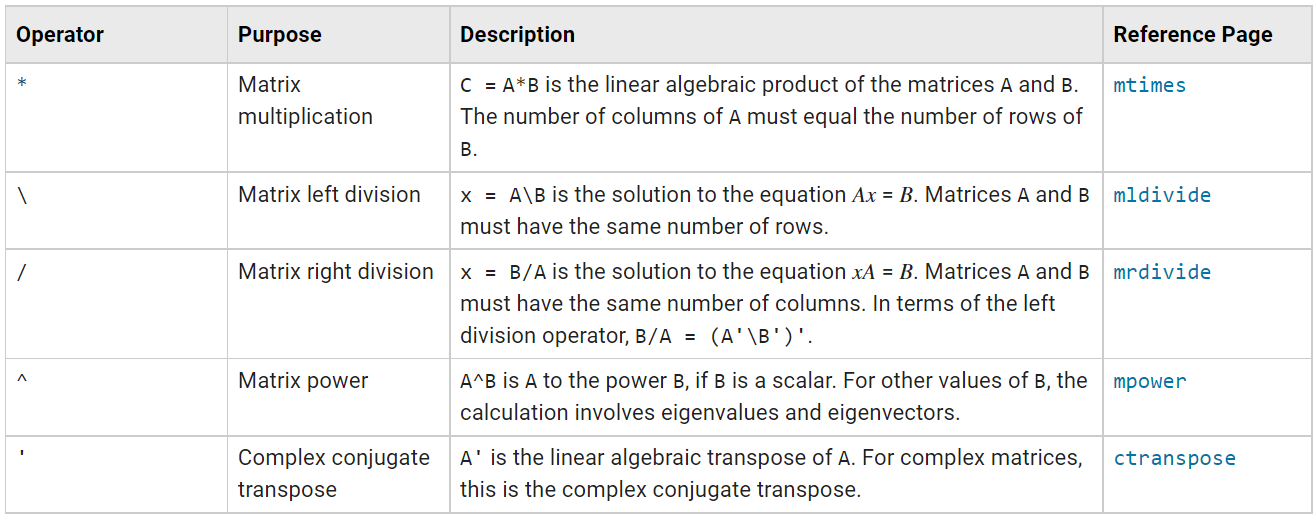

*Tomado de *[*MathWorks: Array vs. Matrix Operations*](https://www.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html)*.*

La suma y resta matricial son similares a la suma y resta tradicional (*operación elemento a elemento*). El resto de operaciones sí cambian significativamente.

## Multiplicación y potencia

El producto o multiplicación matricial se define como:


$$\textrm{AB}={\left(a_{\textrm{ij}} \right)}_{m\times n} {\left(b_{\textrm{ij}} \right)}_{n\times p} ={\left(\sum_{k=1}^n a_{\textrm{ik}} b_{\textrm{kj}} \right)}_{m\times p}$$


O escrito de otra forma:


$$\begin{array}{l}
\textrm{AB}=\left\lbrack \begin{array}{cccc}
a_{11}  & a_{12}  & \ldotp \ldotp \ldotp  & a_{1n} \\
a_{21}  & a_{22}  & \ldotp \ldotp \ldotp  & a_{2n} \\
\vdots  & \vdots  & \ddots  & \vdots \\
a_{m1}  & a_{m2}  & \ldotp \ldotp \ldotp  & a_{\textrm{mn}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
b_{11}  & b_{12}  & \ldotp \ldotp \ldotp  & b_{1p} \\
b_{21}  & b_{22}  & \ldotp \ldotp \ldotp  & b_{2p} \\
\vdots  & \vdots  & \ddots  & \vdots \\
b_{n1}  & b_{n2}  & \ldotp \ldotp \ldotp  & b_{\textrm{np}} 
\end{array}\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;=\left\lbrack \begin{array}{cccc}
a_{11} b_{11} +a_{12} b_{21} +\cdots +a_{1n} b_{n1}  & \sum_{k=1}^n a_{1k} b_{k2}  & \ldotp \ldotp \ldotp  & \sum_{k=1}^n a_{1k} b_{\textrm{kp}} \\
a_{21} b_{11} +a_{22} b_{21} +\cdots +a_{2n} b_{n1}  & \sum_{k=1}^n a_{2k} b_{k2}  & \ldotp \ldotp \ldotp  & \sum_{k=1}^n a_{2k} b_{\textrm{kp}} \\
\vdots  & \vdots  & \ddots  & \vdots \\
a_{m1} b_{11} +a_{m2} b_{21} +\cdots +a_{\textrm{mn}} b_{n1}  & \sum_{k=1}^n a_{\textrm{mk}} b_{k2}  & \ldotp \ldotp \ldotp  & \sum_{k=1}^n a_{\textrm{mk}} b_{\textrm{kp}} 
\end{array}\right\rbrack 
\end{array}$$


**Figura 2.** Ejemplo de multiplicación matricial con calificaciones y ponderaciones.

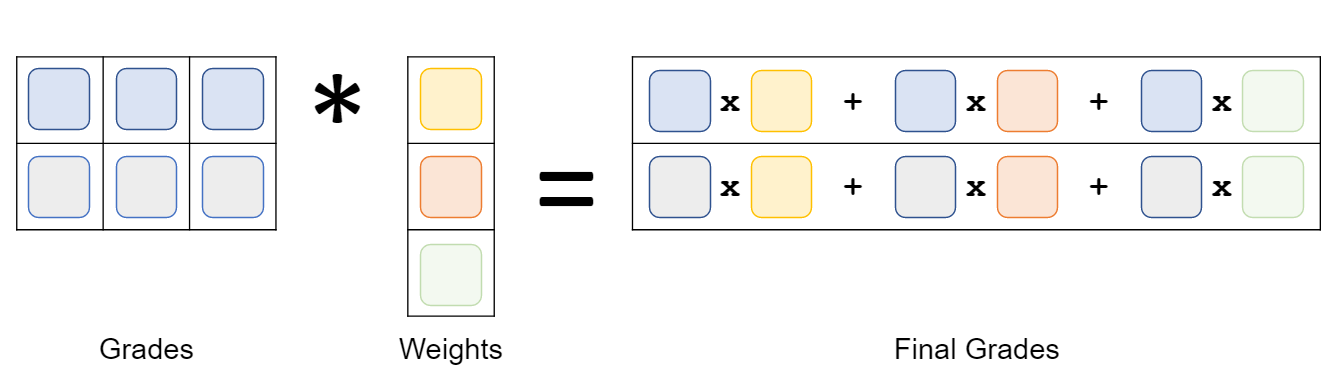

*Tomado de MATLAB Fundamentals (R2022a) de MathWorks.*

Un pequeño tip para verificar si una matriz se puede multiplicar con otra es observar el número de columnas de la matriz de la derecha y el número de filas de la matriz de la izquierda. Si estos números son iguales, entonces la multiplicación entre estas matrices es posible. Recordar que el producto matricial no es conmutativo, por ende, $\textrm{AB}\not= \textrm{BA}$.

**Figura 3.** Verificación de dimensiones para realizar la multiplicación matricial.

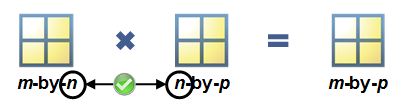

*Tomado de MATLAB Fundamentals (R2022a) de MathWorks.*

**Figura 4.** Matriz resultante de la multiplicación matricial.

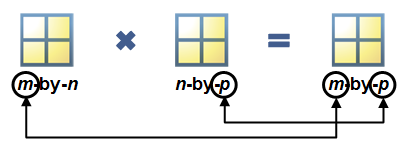

*Tomado de MATLAB Fundamentals (R2022a) de MathWorks.*

% Ingrese su código aquí :)

Por otra parte, la potencia de una matriz es posible únicamente para matrices cuadradas.

% Ingrese su código aquí :)

## División izquierda, división derecha y transposición

Las divisiones tanto izquierda como derecha dentro de MATLAB permiten resolver un sistema de ecuaciones lineales.

- La división izquierda (`\`) permite resolver el sistema $Ax = b$, donde $x=A\backslash b$. La matriz $A$ y el vector $b$ deben tener el mismo número de filas. El sistema ingresado debe ser similar al mostrado a continuación:


$$\begin{array}{l}
a_1 x_1 +a_2 x_2 +a_3 x_3 =b_1 \\
a_4 x_1 +a_5 x_2 +a_6 x_3 =b_2 \\
a_7 x_1 +a_8 x_2 +a_9 x_3 =b_3 
\end{array}$$



$$A=\left\lbrack \begin{array}{ccc}
a_1  & a_2  & a_3 \\
a_4  & a_5  & a_6 \\
a_7  & a_8  & a_9 
\end{array}\right\rbrack ,\;x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack ,\;b=\left\lbrack \begin{array}{c}
b_1 \\
b_2 \\
b_3 
\end{array}\right\rbrack$$


- La división derecha (`/`) permite resolver el sistema $xA = b$, donde $x = b/A$. La matriz $A$ y el vector $b$ deben tener el mismo número de columnas. El sistema ingresado debe ser similar al mostrado a continuación:


$$\begin{array}{l}
a_1 x_1 +a_2 x_2 +a_3 x_3 =b_1 \\
a_4 x_1 +a_5 x_2 +a_6 x_3 =b_2 \\
a_7 x_1 +a_8 x_2 +a_9 x_3 =b_3 
\end{array}$$



$$A=\left\lbrack \begin{array}{ccc}
a_1  & a_4  & a_7 \\
a_2  & a_5  & a_8 \\
a_3  & a_6  & a_9 
\end{array}\right\rbrack ,\;x=\left\lbrack \begin{array}{ccc}
x_1  & x_2  & x_3 
\end{array}\right\rbrack ,\;b=\left\lbrack \begin{array}{ccc}
b_1  & b_2  & b_3 
\end{array}\right\rbrack$$


Donde $A$ es la matriz de coeficientes, $b$ es el vector columna de términos independientes y $x$ es el vector columna solución.

% Ingrese su código aquí :)

Finalmente, la transposición matricial devuelve la conjugada de los elementos de la matriz. Esto es relevante cuando la matriz es compleja, es decir, sus elementos son números complejos.

% Ingrese su código aquí :)

## Material adicional

- [Matrices en el entorno de MATLAB](https://www.mathworks.com/help/matlab/math/matrices-in-the-matlab-environment.html)

- [Operaciones matriciales](https://www.mathworks.com/help/matlabmobile/ug/matrix-operations.html)

- [Operaciones arreglo vs. Operaciones matriciales](https://www.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html)